% Jep Brinkmann Thesis HMM example
clc; close all;

Initiate the HMM

k = number of states

d = number of possible observational values

T = transition matrix

O = emission matrix

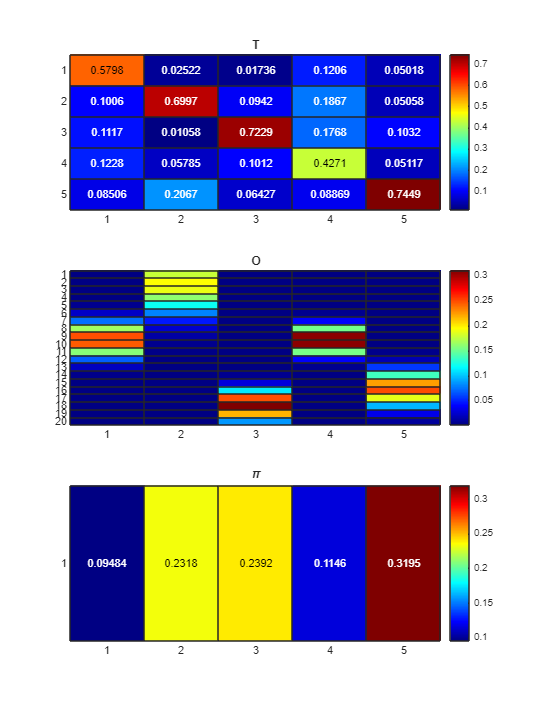

k = 5;
d = 20;

options.method = "random";
options.lambda = 5;

[T, O, pi, k, d] = generateHMM(k, d, 1, options);


figure('Renderer', 'painters', 'Position', [10 10 900 1200])


subplot(3, 1, 1);
h = heatmap(T, Colormap=jet());
h.Title = 'T';

subplot(3, 1, 2);
h = heatmap(O, Colormap=jet());
h.Title = 'O';

subplot(3, 1, 3);
h = heatmap(pi, Colormap=jet());
h.Title = '\pi';

Generate an observational sequence based on the defined HMM

D = {};
D{1} = Stochasticize(O * diag(pi) * T' * inv(diag(T * pi')));
D{2} = O;
D{3} = Stochasticize(O * T);
P3_inf = cpdgen(D)/k;


T_seq = 1e6;

Taug = [0, pi; zeros(k, 1), T'];
Oaug = [zeros(1, d); O'];
[seq,states] = hmmgenerate(T_seq, Taug, Oaug);

tic
[P3_n, convergence] = estimate_joint_prob(seq, d, P3_inf);
toc

Elapsed time is 0.246650 seconds.


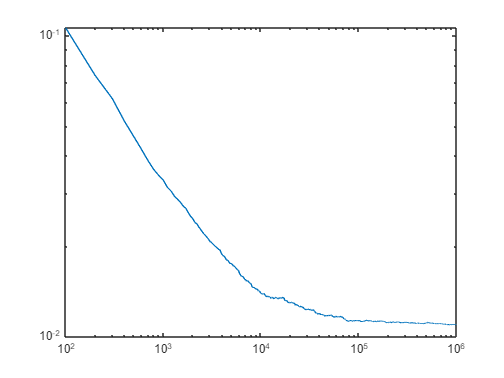


figure()
loglog(linspace(0, T_seq, length(convergence)), convergence)


options.maxIter = 5000;
options.th_relerr = 1e-17;

epsilon = 1e-3;
T_init = Stochasticize(eye(k) + epsilon * rand(k,k));
O_init = Stochasticize(ones(d, k) + epsilon * rand(d, k));

tic
[C1, C2, C3, output] = cpd_als_3d_hmm_initialization(P3_n, k, T_init, O_init, options);
% [C1, C2, C3, c, output] = cpd_als_3d(P3_inf, k, options);
toc

Elapsed time is 1.394974 seconds.



k_A = krushkal_rank(C1);
k_B = krushkal_rank(C2);
k_C = krushkal_rank(C3);

if((k_A + k_B + k_C) >= (2 * k + 2))
    display("Decomposition is unique according to krushkal rank theorem");
else
    display("Decomposition is NOT unique according to krushkal rank theorem");
end

    "Decomposition is unique according to krushkal rank theorem"



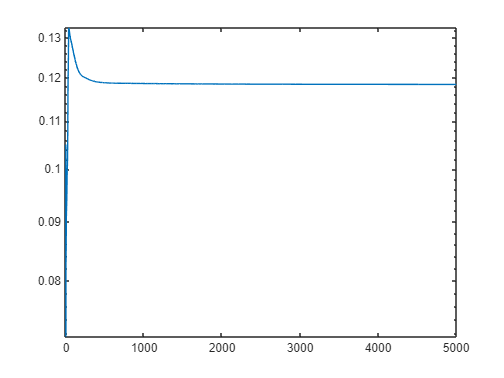


B1 = Stochasticize(C1);
B2 = Stochasticize(C2);
B3 = Stochasticize(C3);

figure()
semilogy(output.relerr)

output.relerr(end)

ans = 0.1185

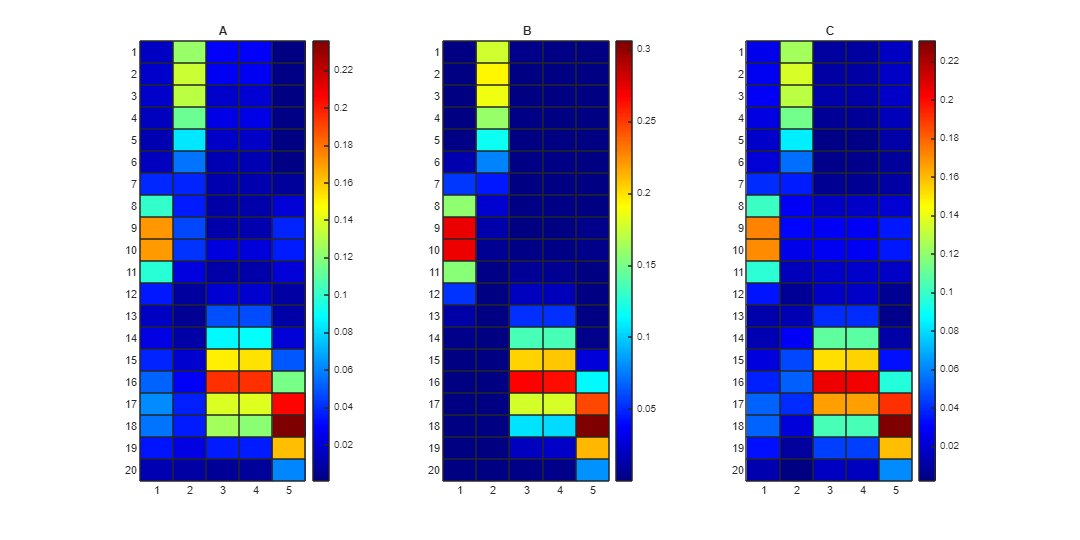

NormalizeAndPlotHM(B1, B2, B3);

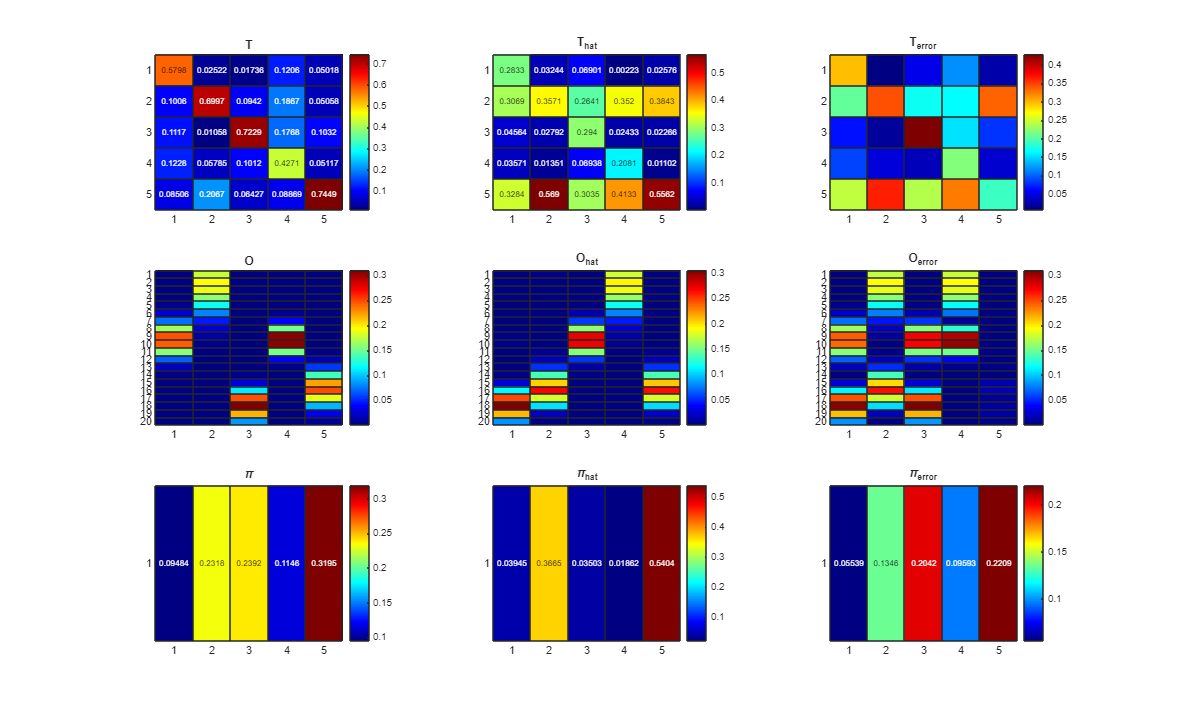

[T_hat, O_hat, pi_hat] = FactorMatrices2HMM({B1, B2, B3});
[T_hat, O_hat, pi_hat] = remove_hmm_permutation_transition(T, T_hat, O_hat, pi_hat);
plotHMMError(T, T_hat, O, O_hat, pi, pi_hat);